clear
load data2.mat
n=length(data.CzasLokalnyUTC0000)

n = 516459

Given from Data2Analysis

T=5; %[s]
fs=1/T; %[Hz]
t_all=T*(0:n-1);

Skraplacz=0.1*data.Skraplacz;
Kompresor1=data.Kompresor1;
Parownik1=0.1*data.Parownik1;
Wlot=0.1*data.Wlot;
TemperaturaOtoczenia=0.1*data.TemperaturaOtoczenia;
Rozmraanie=data.Rozmraanie;
WentylatorParownika=data.WentylatorParownika;
ZawrOdszraniania=data.ZawrOdszraniania;

X_all=[ZawrOdszraniania,Kompresor1,WentylatorParownika,Rozmraanie,...
    TemperaturaOtoczenia,Skraplacz,Wlot,Parownik1]';

[X,~]  = GetRidOfNans(X_all);
day=24*60*60*fs

day = 17280

t=T*(1:day);
X=X';
X=X(:,1:day);
size(X)

ans =            8       17280


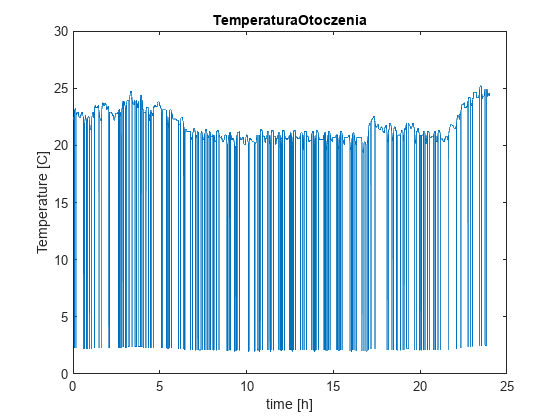

plot(t/(60*60),X(5,:))
title('TemperaturaOtoczenia')
xlabel('time [h]')
ylabel('Temperature [C]')

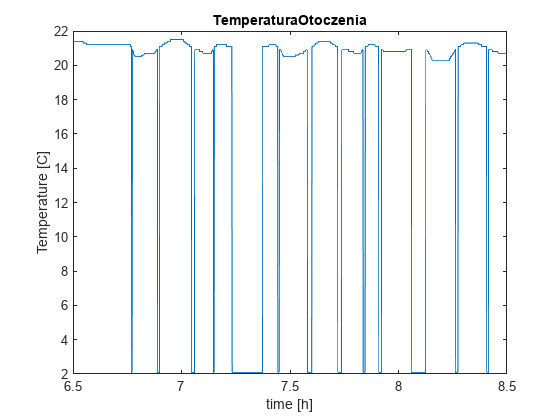

plot(t/(60*60),X(5,:))
title('TemperaturaOtoczenia')
xlabel('time [h]')
ylabel('Temperature [C]')
xlim([6.5,8.5])

We assume that the room temperature doesnt jump from 20+ to 2.1 deg Celcius 8 times per hour. This should be treated as a measurement error.

Let's try a fir filter:

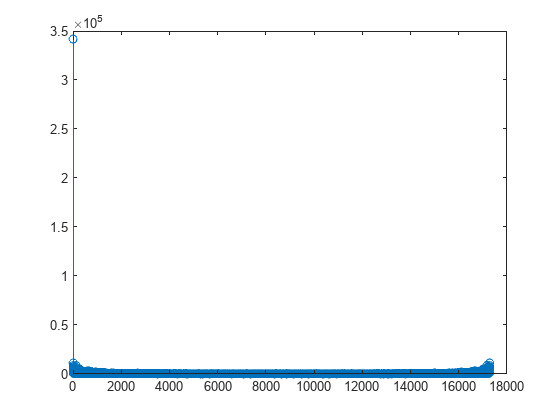

mag=abs(fft(X(5,:)));   
stem(mag)

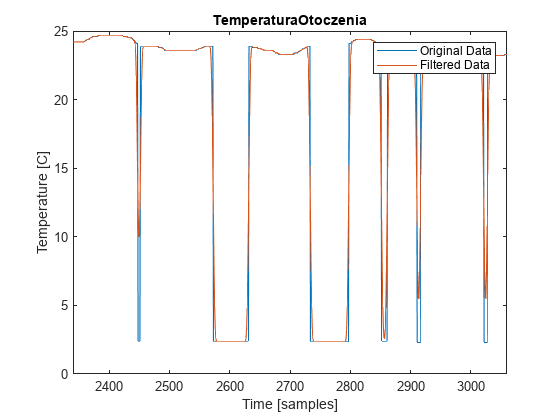

dataFiltered = FilterDataL(X(5,:));
plot(X(5,:),'DisplayName', 'Original Data');hold on
plot(dataFiltered,'DisplayName', 'Filtered Data');hold off
title('TemperaturaOtoczenia')
xlabel('Time [samples]')
ylabel('Temperature [C]')
xlim([6.5*(360),8.5*(360)])
legend

Filter clearly doesn't work

Lets try interpolation of select values

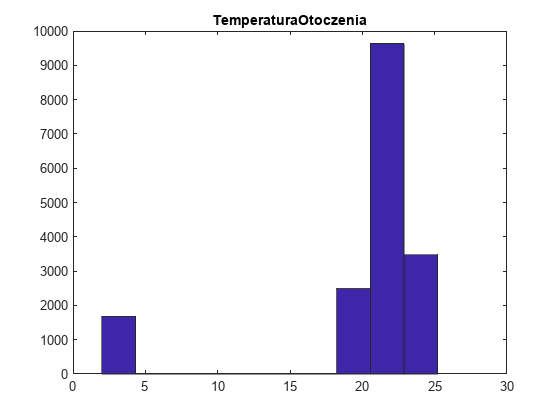

hist(X(5,:))
title('TemperaturaOtoczenia')

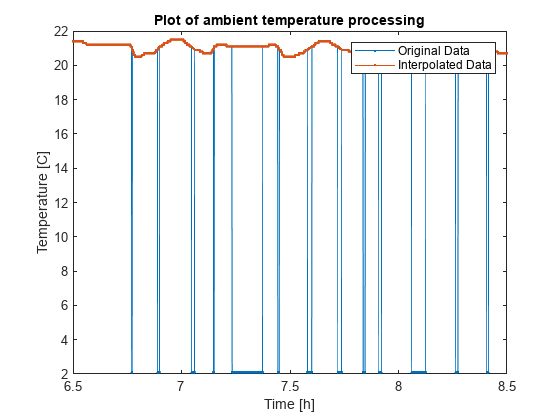

% Identify indices of error values
error_indices = find(X(5,:) <= 5);
non_error_indices = setdiff(1:numel(X(5,:)), error_indices);

new = interp1(t(non_error_indices), X(5,non_error_indices), t, 'linear');

% Plot original and interpolated data
plot(t/(60*60),X(5,:), '.-', 'DisplayName', 'Original Data');
hold on;
plot(t/(60*60),new, '.-', 'DisplayName', 'Interpolated Data');hold off
xlabel('Time [h]')
ylabel('Temperature [C]')
title('Plot of ambient temperature processing')
xlim([6.5,8.5])
legend;

X_new(1,:)=new;

Data seems to properly reflect room temperature now.

For condensor:

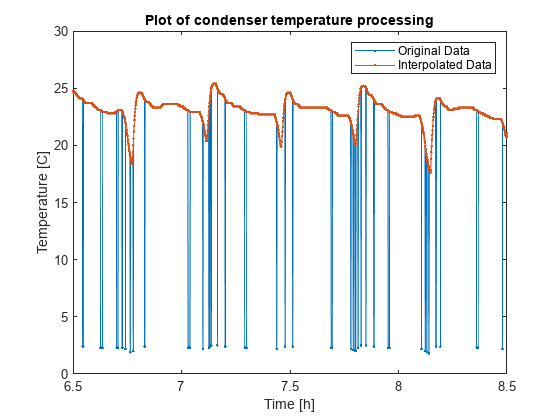

data_interp = InterpolateData(X(6,:),[0,5],t);
% Plot original and interpolated data
plot(t/(60*60),X(6,:), '.-', 'DisplayName', 'Original Data');
hold on;
plot(t/(60*60),data_interp, '.-', 'DisplayName', 'Interpolated Data');hold off
title('Plot of condenser temperature processing')
xlabel('Time [h]');
ylabel('Temperature [C]')
xlim([6.5,8.5])
legend;

X_new(2,:)=data_interp;

For fridge inside:

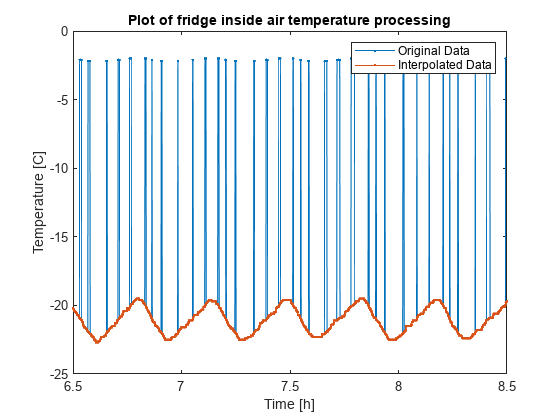

data_interp = InterpolateData(X(7,:),[-5,0],t);
% Plot original and interpolated data
plot(t/(60*60),X(7,:), '.-', 'DisplayName', 'Original Data');
hold on;
plot(t/(60*60),data_interp, '.-', 'DisplayName', 'Interpolated Data');hold off
title('Plot of fridge inside air temperature processing')
xlabel('Time [h]');
ylabel('Temperature [C]')
xlim([6.5,8.5])
legend;

X_new(3,:)=data_interp;

Evaporator:

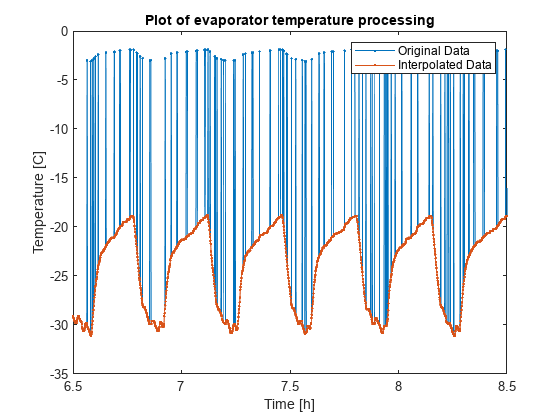

data_interp = InterpolateData(X(8,:),[-5,0],t);
% Plot original and interpolated data
plot(t/(60*60),X(8,:), '.-', 'DisplayName', 'Original Data');
hold on;
plot(t/(60*60),data_interp, '.-', 'DisplayName', 'Interpolated Data');hold off
title('Plot of evaporator temperature processing')
xlabel('Time [h]');
ylabel('Temperature [C]');
xlim([6.5,8.5])
legend;

X_new(4,:)=data_interp;

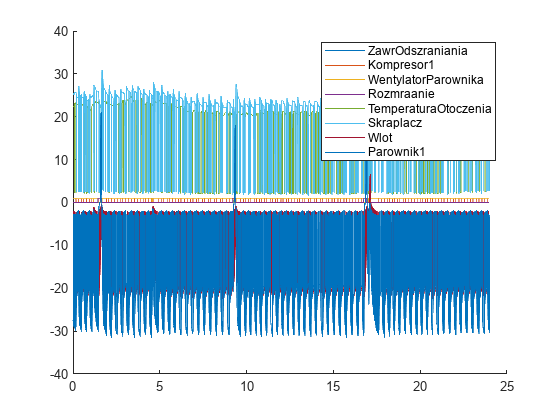

[dataWithoutNans,nan_indices]  = GetRidOfNans(X);
figure 
hold on
for i = 1:8
    plot(t/(60*60),(X(i,:)))
end
legend('ZawrOdszraniania','Kompresor1','WentylatorParownika','Rozmraanie',...
    'TemperaturaOtoczenia','Skraplacz','Wlot','Parownik1')
hold off

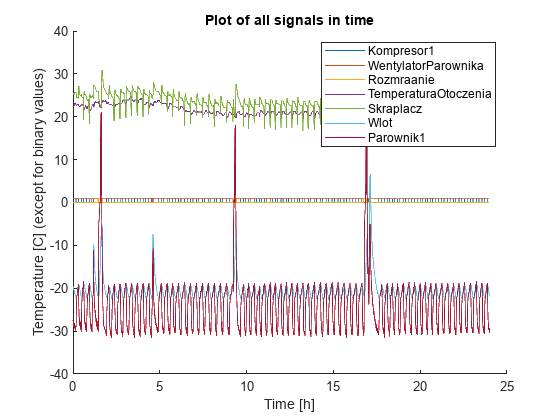

figure 
hold on
for i = 2:4
    plot(t/(60*60),(X(i,:)))
end
for i = 1:4
    plot(t/(60*60),(X_new(i,:)))
end
xlabel('Time [h]')
ylabel('Temperature [C] (except for binary values)')
title('Plot of all signals in time')
legend('Kompresor1','WentylatorParownika','Rozmraanie',...
    'TemperaturaOtoczenia','Skraplacz','Wlot','Parownik1')
hold off

function Hd = filterFL
%FILTERF Returns a discrete-time filter object.

% MATLAB Code
% Generated by MATLAB(R) 9.14 and Signal Processing Toolbox 9.2.
% Generated on: 25-Mar-2024 10:36:58

% Equiripple Lowpass filter designed using the FIRPM function.

% All frequency values are in Hz.
Fs = 48000;  % Sampling Frequency

Fpass = 5;            % Passband Frequency
Fstop = 10000;           % Stopband Frequency
Dpass = 0.057501127785;  % Passband Ripple
Dstop = 0.0001;          % Stopband Attenuation
dens  = 16;              % Density Factor

% Calculate the order from the parameters using FIRPMORD.
[N, Fo, Ao, W] = firpmord([Fpass, Fstop]/(Fs/2), [1 0], [Dpass, Dstop]);

% Calculate the coefficients using the FIRPM function.
b  = firpm(N, Fo, Ao, W, {dens});
Hd = dfilt.dffir(b);

% [EOF]
end

function dataFiltered = FilterDataL(data)

[n,m]=size(data);

%Forcing row vectros
if n>m
    data=data';
    n=temp;
    n=m;
    m=temp;
end

%Init Filter
Hd=filterFL;

%Filtering and scaling all signals one by one
for i=1:n
    
%Applying filter
x=Hd.filter(data(i,:));

%Scaling the filtered signal 
group_delay = floor((length(Hd.Numerator) - 1)/2);
x = x(group_delay+1:end);

scale_factor = max(data(i,:)) / max(x);
x = x * scale_factor;

%Appending Filtered and scaled signal
dataFiltered(i,:)=x;
end
end